dataDir = 'datasets';
addpath('../');

## RNN-DBSCAN clustering tests

The original author's did not release their code, so these tests are for me to see if my implementation is correct, or at least performs reasonably.

SPDX-License-Identifier: BSD-3-Clause

## Tests on datasets used in their paper

They report performance on some shape-based synthetic datasets (Table 3). I am going to attempt to repeat their results on these datasets:

- aggregation

- d31

- flame

- jain

- r15

- spiral

- pathbased

These datasets are from the [University of Finland shape sets](http://cs.uef.fi/sipu/datasets/). Some of them are directly from that site, and some are from this [Github repo](https://github.com/milaan9/Clustering-Datasets) that converted the datasets into mat files. 

In the paper, they report the Adjusted Rand Index (ari), purity, # of clusters, and # of noise points. I am just going to compare ari, # of clusters, and # of noise points.

They sweep k from 1 to 100 and find the k that results in the max ARI, so I will do the same.

`rand_index` is by Chris McComb on [GitHub](https://github.com/cmccomb/rand_index); it needs to be on the MATLAB path

### Aggregation

#### original labels

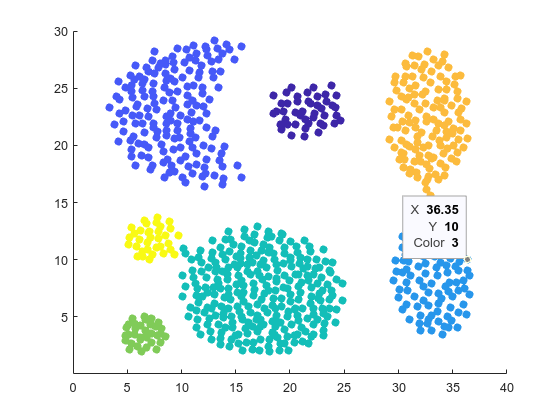

load([dataDir filesep 'aggregation.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

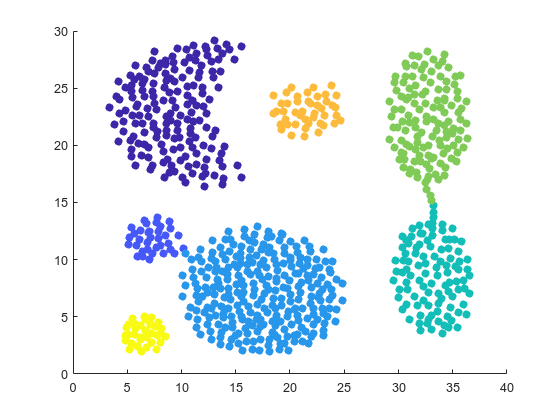

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri

maxAri = 0.9949

length(rnnDbscan.Clusters)

ans = 7

length(rnnDbscan.Outliers)

ans = 0

They were able to achieve a max ari of 0.998 and had 0 noise points.

### D31

#### original labels

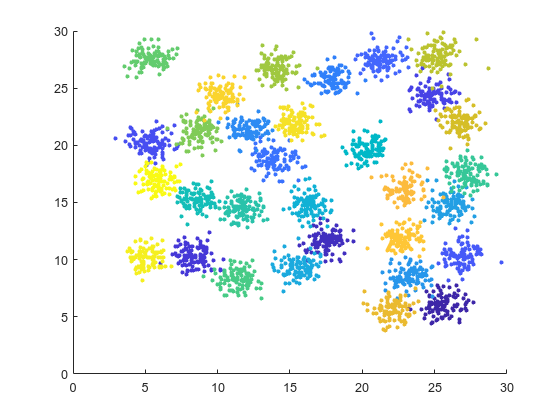

load([dataDir filesep 'D31.mat'])
scatter(data(:,1), data(:,2), 10, label, 'filled')

#### RNN-DBSCAN results

maxAri = intmin;
kMaxAri = 1;

for k = 1:100
    rnnDbscan = RnnDbscan(data, k, k + 1);
    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

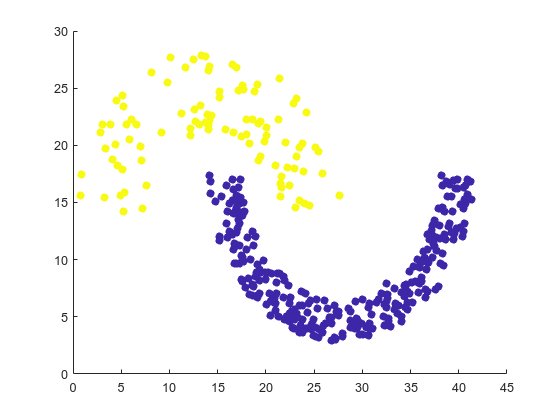

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 10, rnnDbscan.Labels, 'filled')

maxAri
length(rnnDbscan.Clusters)
length(rnnDbscan.Outliers)

They had an ari of 0.896, 31 clusters, and 167 noise points. I'm not really sure how to compare those results. The ari is similar enough. There are 31 true clusters in the dataset.

### Jain

#### original labels

load([dataDir filesep 'jain.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

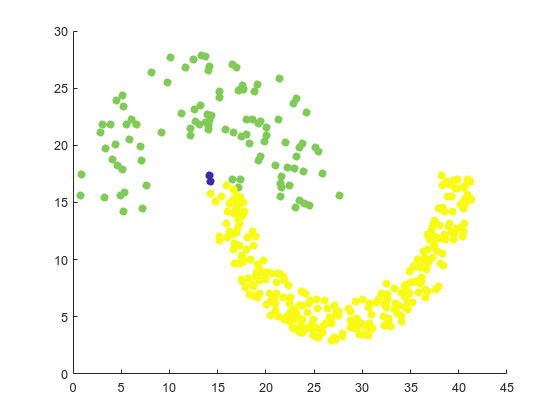

maxAri = intmin;

kMaxAri = 1;


maxAri = 0.9501

for k = 1:100

ans = 2

    rnnDbscan = RnnDbscan(data, k, k + 1);

ans = 2

    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

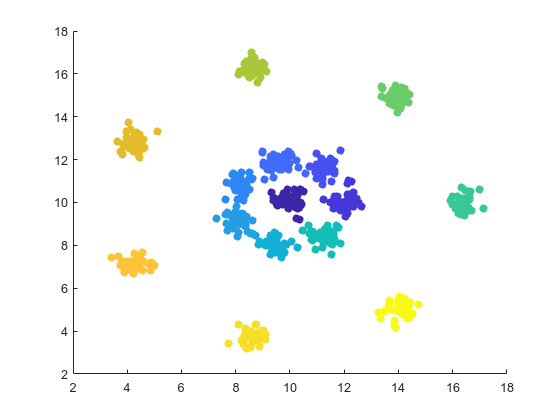

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);

rnnDbscan.cluster();

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri
length(rnnDbscan.Clusters)
length(rnnDbscan.Outliers)

Their ari is 0.983, 2 clusters and 2 noise points. 

I think the order in which points are assigned to clusters is causing those 3 green points that clearly should be yellow to be misclassified. The green cluster is the first cluster that gets looked at, and the three misclassified points could belong to either cluster by the cluster definition given in the paper. When border points can belong to multiple clusters, I could "fix" the above behavior by assigning to the points to their closest cluster; that would ultimately be the best thing to do.

### R15

#### original labels

load([dataDir filesep 'R15.mat'])
scatter(data(:,1), data(:,2), 40, label, 'filled')

#### RNN-DBSCAN results

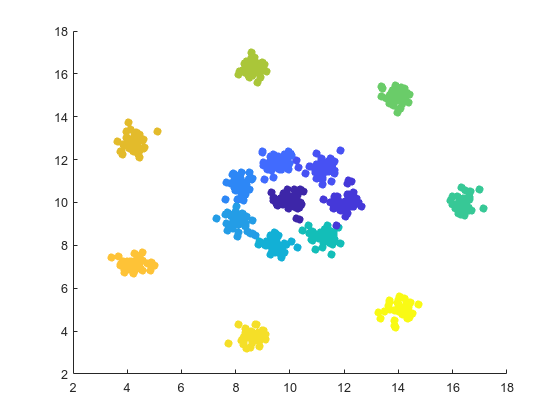

maxAri = intmin;

kMaxAri = 1;


maxAri = 0.9822

for k = 1:100

ans = 15

    rnnDbscan = RnnDbscan(data, k, k + 1);

ans = 0

    rnnDbscan.cluster();
    ari = rand_index(label, rnnDbscan.Labels, 'adjusted');
    if ari > maxAri
        maxAri = ari;
        kMaxAri = k;
    end
end

rnnDbscan = RnnDbscan(data, kMaxAri, kMaxAri + 1);
rnnDbscan.cluster();

scatter(rnnDbscan.Data(:,1), rnnDbscan.Data(:,2), 40, rnnDbscan.Labels, 'filled')

maxAri
length(rnnDbscan.Clusters)
length(rnnDbscan.Outliers)

They report an ari of 0.984, 15 clusters and 3 noise points